# Kaw Textbook Code Validation

format shortG

## Lamina Examples

### Example 2.15

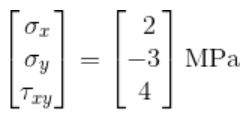

60[°](https://www.degreesymbol.net/) angle graphite/epoxy lamina.

REQUIRED: 

- Strength ratio using maximum stress failure theory

**SOLUTION**: 

- 16.33

n_trials = 1;
theta = [60];

% loading conditions Nx/y/xy [N/m], Mx/y/xy [Nm/m]
Nx = (2e6)*.005; Ny = -(3e6)*.005; Nxy = (4e6)*.005; Mx = 0; My = 0; Mxy = 0; % ply thickness = 5mm
F = [Nx; Ny; Nxy; Mx; My; Mxy];

% specify sds for each simulation for which to generate data
sd = repelem(0,11)';


failure_theories = {@maxstress_FPF};
maxstress_SR = discountmethod_validation(n_trials,theta,F,sd,failure_theories);
maxstress_SR{1}

ans =        16.326


### Example 2.18

60[°](https://www.degreesymbol.net/) angle graphite/epoxy lamina

REQUIRED: 

- Strength ratio using (modified) Tsai-Hill failure theory

**SOLUTION**: 

- 16.06

failure_theories = {@tsai_hill_FPF};
tsai_hill = discountmethod_validation(n_trials,theta,F,sd,failure_theories);
tsai_hill{1}

ans =        16.061


### Example 2.19

60[°](https://www.degreesymbol.net/) angle graphite/epoxy lamina.

REQUIRED: 

- Strength ratio using Tsai-Wu failure theory

**SOLUTION**: 

- 22.49 (Hoffman)

- 22.39 (Mises-Hencky)

failure_theories = {@tsai_wu_H_FPF @tsai_wu_MH_FPF};
tsai_wu = discountmethod_validation(n_trials,theta,F,sd,failure_theories);
tsai_wu{1,1,1} % Hoffman

ans =        22.489


tsai_wu{1,1,2} % Mises-Hencky

ans =        22.389


## Laminate Examples

### Example 4.3

[0/30/-45] graphite/epoxy lamina subjected to $N_x =N_y =1000\;N\backslash m$. Ply thickness = $5 \ mm$.

REQUIRED: 

- Midplane strains and curvatures

- Global and local stresses on the top of the 30[°](https://www.degreesymbol.net/) ply

**SOLUTION**: 

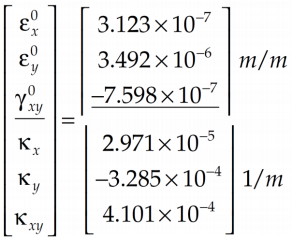

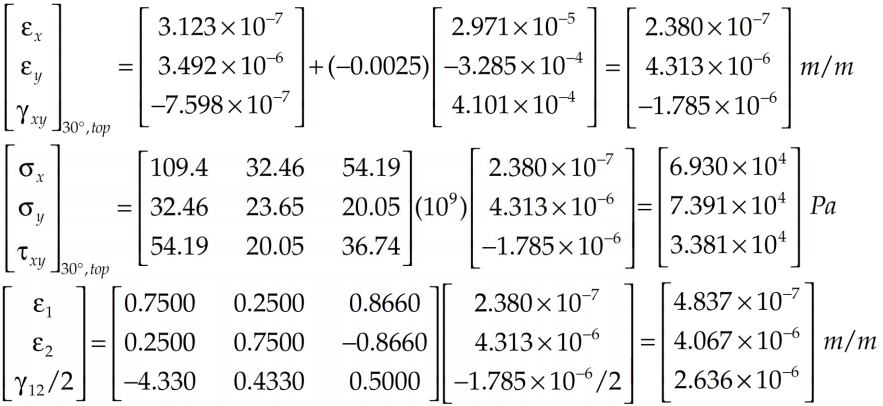

n_trials = 1;
theta = [0 30 -45];

% loading conditions Nx/y/xy [N/m], Mx/y/xy [Nm/m]
Nx = 1000; Ny = 1000; Nxy = 0; Mx = 0; My = 0; Mxy = 0; 
F = [Nx; Ny; Nxy; Mx; My; Mxy];

[ A1, B1, D1, ~, ~, ~, ~, ~, ~, Qbar, ~, Z_i, ~, E11, E22, G12, ply_thickness_i ] = generatelaminate( theta, sd(1:6,1) );
[ global_strain, mp_eps_kap ] = computeglobalstrain( F, A1, B1, D1, Z_i );
mp_strain = mp_eps_kap(1:3)

mp_strain =    3.1229e-07
   3.4917e-06
  -7.5984e-07


mp_curvature = mp_eps_kap(4:6)

mp_curvature =    2.9714e-05
   -0.0003285
   0.00041015


[ plystress ] = computeglobalsurfacestress( Qbar(:,:,2), global_strain(:,:,2:3) );
topof30degply_globalstrain = global_strain(:,:,2)

topof30degply_globalstrain =    2.3801e-07
    4.313e-06
  -1.7852e-06


topof30degply_globalstress = plystress(:,:,1)

topof30degply_globalstress =         69297
        73914
        33808


[ local_stress, local_strain ] = computelocalstressstrain( global_strain, Qbar, theta, E11, E22, G12 );
topof30degply_localstrain = local_strain(:,:,3)

topof30degply_localstrain =    4.8373e-07
   4.0672e-06
   2.6364e-06


topof30degply_localstress = local_stress(:,:,3)

topof30degply_localstress =         99730
        43482
        18903


## Ply-by-ply Failure

### Example 5.3

[0/90/0] graphite epoxy laminate subjected to tensile normal load in the x-direction. Ply thickness = $5 \ mm$.

REQUIRED: 

- Ply-by-ply failure loads using Tsai-Wu (Mises-Hencky) failure theory

**SOLUTION**: 

- First ply failure load = $7.227 \times 10^{6} \ N/m$ (Ply 2 fails)

- Last ply failure load = $1.500 \times 10^{7} \ N/m$ (Plies 1 and 3 fail)

n_trials = 1;
theta = [0 90 0];

% loading conditions Nx/y/xy [N/m], Mx/y/xy [Nm/m]
Nx = 1; Ny = 0; Nxy = 0; Mx = 0; My = 0; Mxy = 0;
F = [Nx; Ny; Nxy; Mx; My; Mxy];

failure_theories = {@tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);
failure_loads = failure_data{1}

failure_loads =    7.2766e+06      1.5e+07


first_ply_failure_ply = failure_data{2}{1}

first_ply_failure_ply =      2


last_ply_failure_ply = failure_data{2}{2}

last_ply_failure_ply =      1     3


# Solidworks Code Validation

The following section compares results of the simulation code to results from Solidworks for laminates under pure tensile loading in the x-direction ($N_x = 1 \ N/m
$).  

## [0 90 0 90 0] - Symmetric Cross-Ply

**Solidworks Results:**

- Maximum Stress = 1.105e7 (ply 2)

- Tsai-Hill = 1.104e7 (ply 2)

- Tsai-Wu = 1.104e7 (ply 2)

theta = [0 90 0 90 0];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    1.1047e+07


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      2


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    1.1045e+07


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      2


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    1.1009e+07


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      2


## [0 90 90 0 90] - Cross-Ply

**Solidworks Results:**

- Maximum Stress = 4.952e6 (ply 5)

- Tsai-Hill = 4.952e6 (ply 5)

- Tsai-Wu = 4.949e6 (ply 5)

theta = [0 90 90 0 90];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    4.9517e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      5


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    4.9516e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      5


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =     4.949e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      5


## [0 90 90 0 90 90 0 0] - Cross-Ply

**Solidworks Results:**

- Maximum Stress = 1.236e7 (ply 2)

- Tsai-Hill = 1.236e7 (ply 2)

- Tsai-Wu = 1.235e7 (ply 2)

theta = [0 90 90 0 90 90 0 0];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =     1.236e+07


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      2


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    1.2359e+07


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      2


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    1.2346e+07


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      2


## [0 30 -45] - Arbitrary

**Solidworks Results (median value over midplane):**

- Maximum Stress = 2.109e6 (ply 3)

- Tsai-Hill = 2.001e6 (ply 3)

- Tsai-Wu = 1.833e6 (ply 3)

theta = [0 30 -45];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    2.1373e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      3


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    1.9747e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      3


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    1.7817e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      3


## [0 90 45 90 0] - Symmetric

**Solidworks Results (median value over midplane):**

- Maximum Stress = 8.448e6 (ply 2)

- Tsai-Hill = 8.329e6 (ply 2)

- Tsai-Wu = 8.152e6 (ply 2)

theta = [0 90 45 90 0];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    8.1741e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      2


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    7.9778e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      2


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    7.7904e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      2


## [45 60 -60 -45] - Antisymmetric

**Solidworks Results (median value over midplane):**

- Maximum Stress = 1.427e6 (ply 2)

- Tsai-Hill = 1.263e6 (ply 1)

- Tsai-Wu = 1.184e6 (ply 1)

theta = [45 60 -60 -45];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    1.3675e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      2


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    1.2201e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      1


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    1.1333e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      1


## [-40 40 -40 40] - Even-Numbered Angle Ply

**Solidworks Results (median value over midplane):**

- Maximum Stress = 3.149e6

- Tsai-Hill = 3.140e6

- Tsai-Wu = 3.096e6

theta = [-40 40 -40 40];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    3.1922e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      4


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    3.1835e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      4


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    3.1127e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      4


## [-40 40 -40 40 -40] - Odd-Numbered Angle-Ply (Symmetric)

**Solidworks Results (median value over midplane):**

- Maximum Stress = 4.071e6

- Tsai-Hill = 4.051e6

- Tsai-Wu = 4.190e6

theta = [-40 40 -40 40 -40];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    4.0762e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      3


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    4.0569e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      3


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =     4.187e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      3


## [30 40 -30 30 -30 -40] - Balanced

**Solidworks Results (median value over midplane):**

- Maximum Stress = 6.987e6

- Tsai-Hill = 6.688e6

- Tsai-Wu = 6.217e6

theta = [30 40 -30 30 -30 -40];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    7.1401e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      1


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    6.7464e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      6


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    6.0752e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      6


## [45 60 -45 -60] - Balanced

**Solidworks Results (median value over midplane):**

- Maximum Stress = 1.181e6

- Tsai-Hill = 1.154e6

- Tsai-Wu = 1.133e6

theta = [45 60 -45 -60];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    1.1317e+06


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      4


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    1.1139e+06


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      4


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    1.0926e+06


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      4


## [45 60 -45 -60] - Balanced

**Solidworks Results (median value over midplane):**

- Maximum Stress = 1.181e6

- Tsai-Hill = 1.154e6

- Tsai-Wu = 1.133e6

theta = [0 10 20 30 45 45 30 20 10 0];
failure_theories = {@maxstress_FPF @tsai_hill_FPF @tsai_wu_MH_FPF};
failure_data = discountmethod_validation(n_trials,theta,F,sd,failure_theories);

maxstress_SR = failure_data{1,1,1}(1)

maxstress_SR =    1.5521e+07


maxstress_failed_ply = failure_data{1,2,1}{1}(1)

maxstress_failed_ply =      5


tsai_hill_SR = failure_data{1,1,2}(1)

tsai_hill_SR =    1.4341e+07


tsai_hill_failed_ply = failure_data{1,2,2}{1}(1)

tsai_hill_failed_ply =      5


tsai_wu_SR = failure_data{1,1,3}(1)

tsai_wu_SR =    1.3468e+07


tsai_wu_failed_ply = failure_data{1,2,3}{1}(1)

tsai_wu_failed_ply =      5
